# Actividad 3

Eleazar Olivas Gaspar A01731405

Modelo 1.

Como podemos ver el modelo 1 solo tiene juntas lineales. por los que empezamos por definir los marcos de referencia con los que se movera el robot.

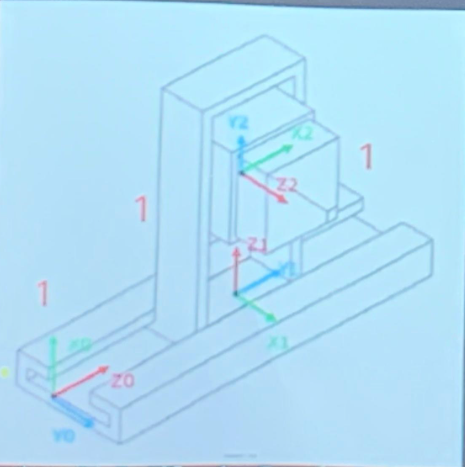

Personalmente me gustan los marcos descritos en la imagen por lo que los marcos se mantendrán igual.

clear all
close all
clc
syms t l1(t) l2(t) l3(t)
RP=[1 1 1]

RP =      1     1     1


disp('Coordenadas generalizadas');

Coordenadas generalizadas


Q= [l1 l2 l3]

$$Q(t) = \left(\begin{array}{ccc} l_{1}\left(t\right) & l_{2}\left(t\right) & l_{3}\left(t\right) \end{array}\right)$$

disp('Velocidades generalizadas');

Velocidades generalizadas


Qp= diff(Q, t)

$$Qp(t) = \left(\begin{array}{ccc} \frac{\partial }{\partial t}l_{1}\left(t\right) & \frac{\partial }{\partial t}l_{2}\left(t\right) & \frac{\partial }{\partial t}l_{3}\left(t\right) \end{array}\right)$$

GDL= size(RP,2)

GDL = 3

GDL_str= num2str(GDL)

GDL_str = '3'

Con el proposito de avanzar más rapido se acumula partes de código más grandes con el fin de dar una explicacion más brebe, por lo que en el código anterior se pueden observar la limpieza de entorno de trabajo, la definicion de las variables simbólicas y de las variables, la configuración del robot y las variables generalizadas.

%Junta 1 
%Posición de la junta 1 respecto a 0
P(:,:,1)= [0; 0; l1];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,1)= [0 0 1;
           0 1 0;
          -1 0 0];

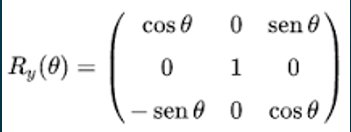

Aqui se puede observar la primera junta de que se mueve respevto a z. y rota 90° positivos en y para dejar el marco acomodado

%Junta 2
%Posición de la junta 2 respecto a 0
P(:,:,2)= [l3; 0;l2];
%Matriz de rotación de la junta 2 respecto a 0
R(:,:,2)= [1 0  0;
           0 0 -1;
           0 1  0];

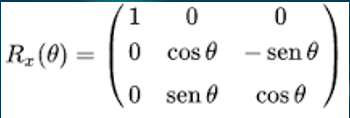

Posteriormente se ve el movimiento lineal respecto al segundo marco, donde el l2 se mueve respecto a z y l3 a x, debido a como se maneja el marco, para depués rotar el marco nuevamente en 90 grados positivos respecto a el eje x.

%Junta 3
%Posición de la junta 3 respecto a 0
P(:,:,3)= [0; 0; 0];
%Matriz de rotación de la junta 3 respecto a 0
R(:,:,3)= [1 0 0;
           0 1 0;
           0 0 1];

Para la junta 3 debido a que no quedan movimientos por ser incluido se añade un vector de 0 y la matriz identidad.

A continuación se ejecuta en un solo bloque el calculo de los jacobianos las homogeneas locales y globales así como las velocidad, el cual es código reciclado de las 2 actividades anteriores.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
%Inicializamos las INVERSAS de las matrices de rotación vistas desde el marco de referencia inercial
RO_inv(:,:,GDL)= R(:,:,GDL); 

for i = 1:GDL
    i_str= num2str(i);
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1])

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i))
    

    RO(:,:,i)= T(1:3,1:3,i);
    RO_inv(:,:,i)= transpose(RO(:,:,i));
    PO(:,:,i)= T(1:3,4,i)
    %pretty(RO(:,:,i));
    %pretty(RO_inv(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1


$$\left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 1 & 0 & 0\\ -1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación global T1


$$\left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 1 & 0 & 0\\ -1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{c} 0\\ 0\\ l_{1}\left(t\right) \end{array}\right)$$

$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Matriz de Transformación local A2


$$\left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 1 & 0 & 0\\ -1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & l_{3}\left(t\right)\\ 0 & 0 & -1 & 0\\ 0 & 1 & 0 & l_{2}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación global T2


$$\left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 1 & 0 & 0\\ -1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 1 & 0 & l_{2}\left(t\right)\\ 0 & 0 & -1 & 0\\ -1 & 0 & 0 & l_{1}\left(t\right)-l_{3}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{c} 0\\ 0\\ l_{1}\left(t\right) \end{array}\right)$$

$$\left(\begin{array}{c} l_{2}\left(t\right)\\ 0\\ l_{1}\left(t\right)-l_{3}\left(t\right) \end{array}\right)$$

$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Matriz de Transformación local A3


$$\left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 1 & 0 & 0\\ -1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & l_{3}\left(t\right)\\ 0 & 0 & -1 & 0\\ 0 & 1 & 0 & l_{2}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación global T3


$$\left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 1 & 0 & 0\\ -1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 1 & 0 & l_{2}\left(t\right)\\ 0 & 0 & -1 & 0\\ -1 & 0 & 0 & l_{1}\left(t\right)-l_{3}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 1 & 0 & l_{2}\left(t\right)\\ 0 & 0 & -1 & 0\\ -1 & 0 & 0 & l_{1}\left(t\right)-l_{3}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{c} 0\\ 0\\ l_{1}\left(t\right) \end{array}\right)$$

$$\left(\begin{array}{c} l_{2}\left(t\right)\\ 0\\ l_{1}\left(t\right)-l_{3}\left(t\right) \end{array}\right)$$

$$\left(\begin{array}{c} l_{2}\left(t\right)\\ 0\\ l_{1}\left(t\right)-l_{3}\left(t\right) \end{array}\right)$$


%Calculamos el jacobiano lineal de forma diferencial
disp('Jacobiano lineal obtenido de forma diferencial');

Jacobiano lineal obtenido de forma diferencial


%Derivadas parciales de x respecto a th1 , th2 y th3
Jv11= functionalDerivative(PO(1,1,GDL), l1);
Jv12= functionalDerivative(PO(1,1,GDL), l2);
Jv13= functionalDerivative(PO(1,1,GDL), l3);
%Derivadas parciales de y respecto a th1 , th2 y th3
Jv21= functionalDerivative(PO(2,1,GDL), l1);
Jv22= functionalDerivative(PO(2,1,GDL), l2);
Jv23= functionalDerivative(PO(2,1,GDL), l3);
%Derivadas parciales de z respecto a th1 , th2 y th3
Jv31= functionalDerivative(PO(3,1,GDL), l1);
Jv32= functionalDerivative(PO(3,1,GDL), l2);
Jv33= functionalDerivative(PO(3,1,GDL), l3);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13;
              Jv21 Jv22 Jv23;
              Jv31 Jv32 Jv33])

$$jv\_d(t) = \left(\begin{array}{ccc} 0 & 1 & 0\\ 0 & 0 & 0\\ 1 & 0 & -1 \end{array}\right)$$


%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
end    

disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


Jv_a= simplify (Jv_a)

$$Jv\_a = \left(\begin{array}{ccc} 0 & 1 & 0\\ 0 & 0 & -1\\ 1 & 0 & 0 \end{array}\right)$$

disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


Jw_a= simplify (Jw_a)

$$Jw\_a = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$


disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp')

$$V(t) = \left(\begin{array}{c} \bar{\frac{\partial }{\partial t}l_{2}\left(t\right)}\\ -\bar{\frac{\partial }{\partial t}l_{3}\left(t\right)}\\ \bar{\frac{\partial }{\partial t}l_{1}\left(t\right)} \end{array}\right)$$

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp')

$$W(t) = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

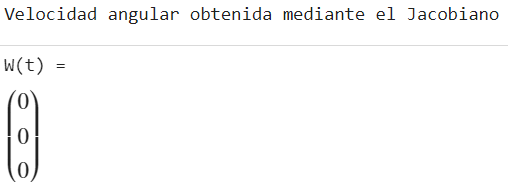

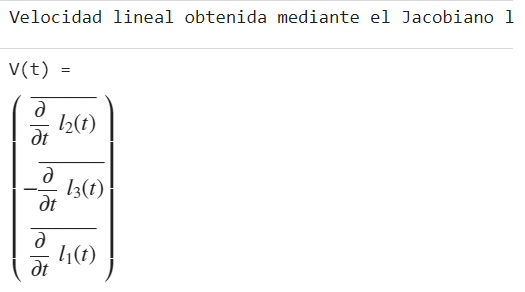

Una vez analisando los resultados podemos ver que tienen sentido debido a que es un ejercicio muy similar al de la actividad 2, en la cual da velocidades angulares de 0 debido a que tiene una configuración prismatica en todas sus juntas, y las velocidades lineales son respectivas a los movimientos del robot.